#  Optical Flow

[⇦ Main Menu](matlab:open('../MainMenu.mlx'))

This script introduces optical flow theory and three core methods to analyze motion in image sequences from real-world scenarios.

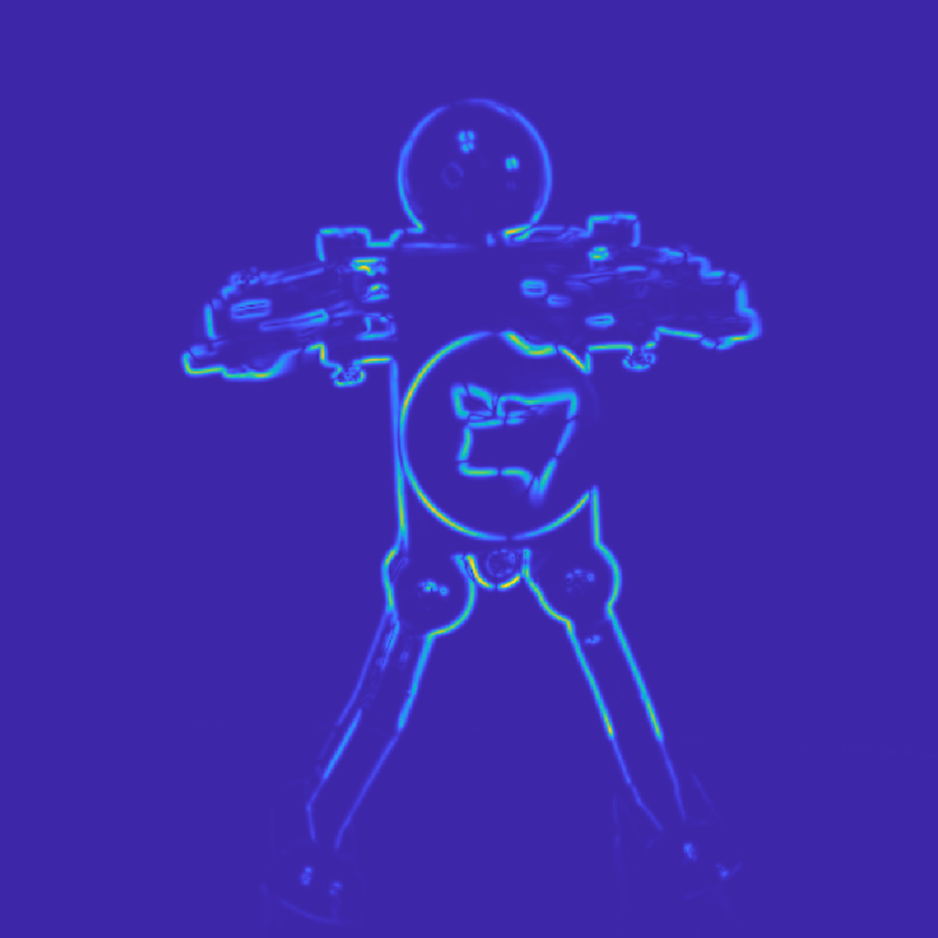

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Overview of Optical Flow Theory

In [EdgeDetectionApplied.mlx](matlab:open('./EdgeDetectionApplied.mlx')) and [RegionSegmentation.mlx](matlab:open('./RegionSegmentation.mlx')), we focused on individual images. As we transition from analyzing single images to sequences of frames or videos, we can begin to understand dynamic scenes more comprehensively. Optical flow is essential in this process, helping us enhance video quality, segment objects, track their movement, and even recognize complex events over time.

**Optical flow** is a technique used to estimate the motion of objects as perceived in a sequence of images. It calculates the movement of brightness patterns, corresponding to apparent motion. Apparent motion refers to the perception of movement in a visual scene, even when there is no actual movement, such as in optical illusions or animations. In contrast, actual motion involves the physical displacement of objects in space, like a plane flying in the sky. 

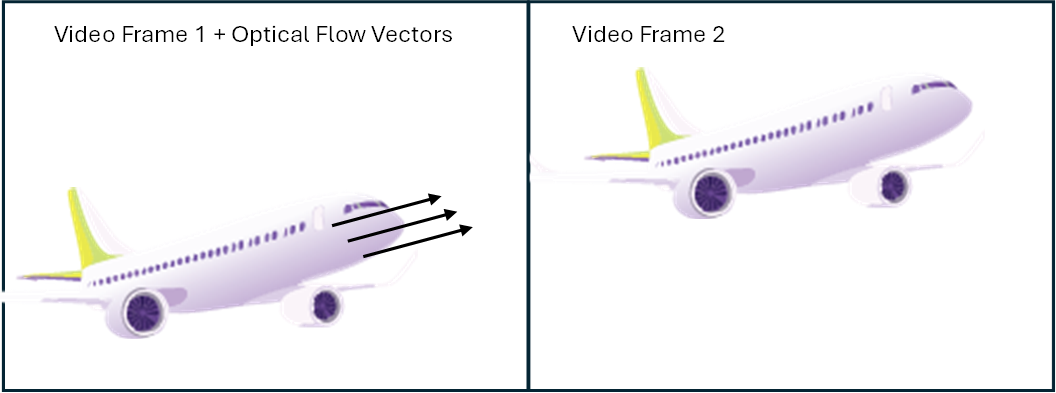

**Optical flow** estimates apparent motion by analyzing changes in pixel intensity in image sequences, which can approximate actual motion under certain conditions. The main goal is to determine the motion of each pixel by tracking the movement of brightness patterns across consecutive frames. This is achieved by calculating **optical flow vectors**, which describe the direction and speed of motion for every point in the scene. These vectors effectively map the apparent movement within the video, providing valuable insights into how objects, surfaces, and edges shift over time.

Optical flow estimates the movement of each pixel between two time points by tracking brightness patterns from one image to the next. We can estimate the motion or the brightness between one frame at $I(x,y,t) $ and the subsequent frame at $I(x,y,t+\delta{t})$. So we are following pixels from one time point to a second time point at $t= t+\delta{t}$.

 **Exercise 1. **In the context of optical flow, what do optical flow vectors describe?

Ans1 = "Select"; % Non-default options include: "The change in brightness patterns over time.", "The direction and speed of motion of features within an image.", "The static position of pixels in an image." and "The random movement of pixels."
CheckAnswer("Exercise1",Ans1)

To calculate optical flow, we rely on two key assumptions:

**Assumption 1**. *Brightness Constancy.* Assume that the brightness is the same for the pixels representing each object over time. 

**Assumption 2**.* Small Motion*. Assume that the motion of an object from one frame to the next is small.                                          

### Assumption 1. Brightness Constancy

As you vary $t$, as a pixel moves, its brightness remains the same. This is given by:

 
$$I(x(t),y(t),t)= \text{Constant}$$


Consider a time sequence t ranging from $t = 1$ to $t = n$. The corresponding image sequence is represented by the frame index $k$, where $k$ spans from $t$ to $t+\delta{t}$. For $ (x(1),y(1))$ until $ (x(k),y(k))$, the intensity (or brightness) of this point is the same for all frames. 

  **Try**. Visualize Assumption 1 to track five points, each corresponding to a specific pixel, across different frames and calculate their intensity in each frame. Optical flow vectors describing the apparent motion of each of the points between two frames are shown on the first frame. Use the colorbar to determine if the intensity for each pixel remains constant. You will observe that each point, maintains a consistent intensity regardless of the frame number.

numFramesA = 2;
[~] = GenScatPlot(numFramesA,false,true);

### Assumption 2. Small Motion

We begin by tracking one pixel $(x,y)$, represented by a colored-dot, that is traveling at a velocity of $(u,v)$ from frame $I(x,y,t) $ to a consecutive frame $I(x,y,t+\delta{t})$. The pixel's new coordinates are $(x + u\delta{t}, y+v\delta{t})$, where the displacements are given by: 

($\delta{x},\delta{y})=(u\delta{t},v\delta{t})$.

  **Try**. Visualize the motion of a pixel traveling from one frame to a consecutive frame.

 
x1 = 10+30*rand(1,1); % Generate a random x coordinate between 10 and 40
y1 = 10+30*rand(1,1); % Generate a random y coordinate between 10 and 40

figure("Units","Normalized",OuterPosition=[0 0 0.5 0.5]) % Set figure to fullscreen
tiledlayout(1,2)
nexttile
scatter(x1,y1,"filled",SeriesIndex=1)
text(x1,y1,"($x,y$)",Interpreter="latex",FontSize=14,Position=[x1-0.5 y1-0.5],VerticalAlignment="top",HorizontalAlignment="right");
delta = 5; % Define a small delta for movement
x2 = x1+delta;
y2 = y1+delta;

hold on
scatter(x2,y2)
quiver(x1,y1,(x2-x1),(y2-y1),1,LineWidth=1.5,MaxHeadSize=1,AutoScale="on"); % Include quiver vectors for the original points
hold off

text(x2,y2,"($x+u\delta{t},y+u\delta{t}$)",Interpreter="latex",FontSize=14,Position=[x2+5 y2+5],VerticalAlignment="bottom",HorizontalAlignment="center");

% Set axis properties
title("$I(x,y,t)$",FontSize=14,Interpreter="latex")
xticks([])
yticks([])
axis padded
ax = gca;
ax.Box = "on";
ax.XLim = [0 70];
ax.YLim = [0 70];

nexttile
scatter(x2,y2,"filled")
text(x2,y2,"($x+u\delta{t},y+u\delta{t}$)",Interpreter="latex",FontSize=14,Position=[x2+5 y2+5],VerticalAlignment="bottom",HorizontalAlignment="center");

% Set axis properties
title("$I(x+\delta{x},y+\delta{y},t+\delta{t})$",FontSize=14,Interpreter="latex")
xticks([])
yticks([])
axis padded
ax = gca;
ax.Box = "on";
ax.XLim = [0 70];
ax.YLim = [0 70];

If we assume that the distance a pixel travels in time $\delta{t}$ is small, then $ t + \delta{t}$ is equivalently $t$. Therefore for a really small space-time step, the brightness of the image point remains constant over time as shown in this equation: 


$$\text {Brightness of a Pixel: } I(x+u\delta{t},y+v\delta{t},t+\delta{t}) = I(x,y,t)$$


### Brightness Constancy Equation

With the two assumptions, for a small space and small time step, we have an equivalent brightness between two consecutive frames. This gives us the Brightness Constancy Equation:


$$\frac{dI}{dt}=\frac{\partial I}{\partial x} \frac{dx}{dt} + \frac{\partial I}{\partial y}  \frac{dy}{dt} + \frac{\partial I}{\partial t} = 0$$
       
$$(\star)$$


which simplifies to:


$$$I_xu+I_yv+I_t=0$$$


where $I_x$ and $I_y$ represent the spatial derivative of image brightness, $I_t$ represents the temporal derivative, and $u$ and $v$ represent the velocities, or the optical flow vectors in the x and y direction. We aim to determine the optical flow vectors $u$ and $v$ for each point in the image. In this equation, the unknowns $u$ and $v$ represent the optical flow vectors. This means we cannot uniquely determine $u$ and $v$ for every point, resulting in an unconstrained system. By expressing this equation in vector form, it becomes evident that we have one equation with two unknowns, $u$ and $v$.


$$\nabla{I}\cdot[u,v]^T+I_t=0$$


There are a few different approaches to providing the additional constraint to make the Brightness Constancy equation $(\star)$ solvable including the Lucas-Kanade method, Horn-Schunck Method, and the Lucas-Kanade Derivative of Gaussian Method.

 **Exercise 2. **What is the primary challenge in solving the Brightness Constancy Equation?

**Solution:**

Ans2 = "Select"; % Non-default options include: "The equation has too many unknowns and not enough constraints.", "The equation is non-linear and difficult to solve.", "The equation does not account for changes in brightness." and "The equation is only applicable to static images."
CheckAnswer("Exercise2",Ans2)

## Lucas-Kanade(LK) Method

### Assumption 3. Spatial Coherence

If instead of looking at individual pixels, we look at a small patch of pixels and assume they share a single velocity, we assume spatial coherence. Mathematically, now, instead of having only one equation with two unknowns, we now have multiple equations for the pixels within the region.  Each pixel in the region contributes to the brightness constancy equation. If we have $5x5$ image patch, for each pixel, $p$, we have 25 equations.


$${\begin{array}{c} I_x(p_1)u+y(p_1)v=I_t(p_1) \\I_x(p_2)u+I+y(p_2)v=I_t(p_2) \\ \vdots \\ I_x(p_{25})u+I+y(p_{25})v=I_t(p_{25}) \end{array}}
$$


If we look at this equation in matrix form, we get: $A$is a $25\times 2$ matrix, $x$ is a $2\times 1$vector, and $b$ is a $25\times 1$vector.


$$\underbrace{\left [\matrix{I_x(p_1) & I_y(p_1) \cr I_x(p_2)&  I_y(p_2)  \cr \vdots &\vdots\cr  I_x(p_{25})&  I_y(p_{25})} \right ]}_\text{A(25x2)}
\underbrace{\left[\matrix{u \cr v}\right]}_\text{x(2x1)} = -
\underbrace{\left[\begin{array}{c} I_t(p_1) \\ I_t(p_2) \\ \vdots \\ I_t(p_{25}) \end{array} \right]}_\text{b(25x1)}
$$


 By assuming the same motion vector for all pixels in the patch, we create an overconstrained system with 25 equations and the same two unknowns, $u$ and $v$.


$${\bf{A}}x=b$$
     
$$(\star\star)$$


 This system, $\star\star$, is then solved using a least-squares approximation, which finds the best-fit solution for the motion vector by minimizing the sum of squared intensity differences across the neighborhood. The least-squares approximation, tells us:

$\hat{x} = \underset{x}{\text{arg min}} \, ||\mathbf{A}x - b||^2$ is equivalent to solving ${\bf{A}}^T{\bf{A}}\hat{x}={\bf{A}}^Tb$.

To obtain the least-squares approximation, we solve:


$$\left [\matrix{\sum_{p \in P} I_x I_x & \sum_{p \in P} I_x I_y \cr\sum_{p \in P} I_y I_x& \sum_{p \in P} I_y I_y  \cr } \right ]
\left[\matrix{u \cr v}\right] = -
\left [\matrix{\sum_{p \in P} I_x I_t \cr \sum_{p \in P} I_y I_t } \right ]
$$


where the summation is over each pixel p in patch $\bf{P}$. This approximation allows us to solve for our two unknowns, $u$ and $v$, our optical flow vectors.

Given that the Lucas-Kanade (LK) method assumes that the optical flow is constant within a small window around each pixel, it performs well in areas with high texture or corners and is effective when the displacement between frames is small. This method is ideal for **object tracking** and **motion detection** in scenarios where the motion is relatively minor. However, the LK method has a notable limitation: it is highly sensitive to noise.

** Demonstration**. Visualize the small patch, $$\bf{P}$$, moving at one velocity.

 
% figure("Units","Normalized",OuterPosition=[0 0 1 1]) % Set figure to fullscreen
VizSpacCoherence;

If we zoom in on the small patch, $\bf{P}$, defined by a blue square with 5 pixels from the demonstration above, we can see that the pixels moving in the same direction inside the patch, all with the same optical flow vector. In this way, we satisfy spatial coherence to solve for $u$ and $v$. 

  **Try**. Observe the pixels in the small patch moving at the same velocity.

numFramesB =2;
intensityTableA = GenScatPlot(numFramesB,true,false);

 **Exercise 3. **What is the primary advantage of using the Lucas-Kanade method for optical flow estimation?

**Solution:**

Ans3 = "Select"; % Non-default options include: "It performs well with minimal motion." and "It ignores the brightness constancy equation."
CheckAnswer("Exercise3",Ans3)

## Lucas-Kanade Derivative of Gaussian (LK-DoG) Method

What if the small motion assumption does not hold? Imagine, you are taking a video with your phone, and you are not using using a tripod. Now, your camera is moving and your video is unstable and so now we have a case where Assumption 2 no longer holds. 

In the previous section, you decreased the image resolution to force the validity of Assumption 1. In the LK-DoG method, images are first blurred with a Gaussian filter to reduce noise and improve gradient calculations. Spatial and temporal image gradients are then computed to formulate optical flow equations. These equations, based on the assumption that pixel intensity remains constant between frames, Assumption 1, are solved using the least squares criterion. This process estimates the optical flow vector for each pixel, indicating motion direction and magnitude, and provides a detailed motion map across the scene.

If we take an image and reduce its size, we get a less-detailed or blurrier version of the original. By continuing to decrease the size, the image becomes increasingly less detailed until it is so blurred that large differences in motion are no longer noticeable. This process of creating multiple levels of increasingly smaller and less detailed images is called a resolution pyramid or a coarse to fine estimation..

By using a resolution pyramid, we can ensure that certain variables remain small. Eventually, all resolutions will be reduced to less than a pixel in size, validating the small motion assumption once more. This reduction in resolution also results in image blurring.

The Lucas-Kanade Derivative of Gaussian (LK-DoG) method builds on the original Lucas-Kanade method, offering improved noise handling. This method is ideal for scenarios where noise reduction and smoothing are crucial, such as **tracking objects** in noisy video sequences. However, the LK-DoG method has a significant limitation: it is computationally intensive.

  **Try**. Adjust the image resolution and blur the pixels to compute lower resolution images. Try to adjust the resolution so that the line going down the image covers approximately the same pixel ranges for the $t$ and $t+\delta{t}$ images.

- *(Optional) Press button to preview image frames.*

- *Move slider to adjust image resolution to blur the image.*

 
n = 1; % Starting frame number
ChosenVid = "FlowerYellow.mp4";
FlowerVid = VideoReader(ChosenVid); % Create a video reader object
frameNumb = FlowerVid.NumFrames;
firstFrame = read(FlowerVid,n);
secondFrame = read(FlowerVid,n+5); % Read the frame that displays a large motion difference

% Clear the VideoReader object to free up resources
clear FlowerVid;

T = im2double(firstFrame); % Convert the first frame to double for processing
TplusdelT = im2double(secondFrame); % Convert the second frame to double for processing

figure
tiledlayout(2,2,TileSpacing="none",Padding="compact") % Set up tiled layout
%
nexttile(1) % Tile (1,1)
imshow(T) % t at resolution original
ylabel("$t$",Interpreter="latex",HorizontalAlignment="left",FontSize=12,Rotation=0) % Insert y-axis label
ax = gca;
ax.XAxisLocation = "top";
xlabel("Resolution of $1$",Interpreter="latex",FontSize=12)

nexttile (3) % Tile (2,1)
imshow(TplusdelT) % t + delta t at resolution original
ylabel("$t+\delta{t}$",Interpreter="latex",HorizontalAlignment="center",FontSize=12,Rotation=0)

Try to adjust the resolution so that the blue line drawn on the image covers approximately the same pixel ranges for the $t$ and $t+\delta{t}$ images.

Na = 1;
if exist("firstFrame","var") && exist("secondFrame","var")
    nexttile(2) % Tile (1,2)
    ResPyr(Na,firstFrame,1)
    ax = gca;
    ax.XAxisLocation = "top";
    NaNew=num2str(Na);
    xlabeltext = "Resolution of $"+NaNew+"$";
    xlabel(xlabeltext,Interpreter="latex",FontSize=12);

    nexttile(4) % Tile (2,2)
    ResPyr(Na,secondFrame,1)
else
    warning("Preview image frames above.")
end

## Horn-Schunck Method

The Horn-Schunck method for optical flow estimation introduces a smoothness constraint. This method assumes that the optical flow vectors change gradually from one pixel to the next, ensuring smooth transitions. Instead of assuming that a small patch of points moves similarly and shares a single velocity, the Horn-Schunck method assumes that neighboring pixels within a small window move in similar ways. By minimizing variations in flow, the Horn-Schunck method aims to produce a more coherent and smooth optical flow field. Unlike the Lucas-Kanade method, which estimates optical flow locally within small neighborhoods, the Horn-Schunck method estimates optical flow across the entire image. It assumes that the flow field is smooth and changes gradually from one pixel to the next. Consequently, this method is more sensitive to noise but produces a denser flow field. The key to achieving this dense flow field is a concept known as the **smoothness constraint**. 

### **The Smoothness Constraint Assumption**

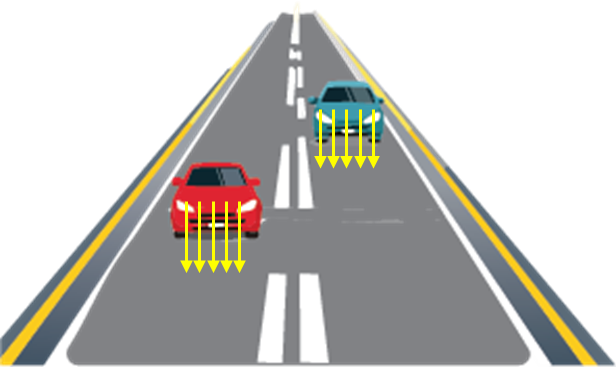

Consider two cars moving down a highway. In optical flow analysis, the smoothness constraint indicates that the pixels within a moving vehicle do not move randomly; instead, they all move together in the same direction. This is because the car is a solid object, and all its parts move as a unit. When we zoom in on a small neighborhood of pixels within the car, we observe that their movement is very similar, reinforcing the idea that they are part of the same object and moving together.

The Horn-Schunck method assumes smoothness in the optical flow across the entire image. This method is ideal for dense **optical flow estimation** and **motion analysis**, both of which require a global view of motion across the entire image. However, the Horn-Schunck method has a notable limitation: the smoothness assumption can lead to inaccuracies in areas with abrupt changes in motion.

 **Exercise 4. **You set up a street camera to detect movement while away from home, which technique would be best to use to measure optical flow?

**Solution:**

Ans4 = "Select"; % Non-default options are "Horn-Schunck", "Lucas-Kanade", and "Lucas-Kanade Derivative of Gaussian" optical flow methods.
CheckAnswer("Exercise4",Ans4)

 **Exercise 5. **Consider a video of monitoring the movement of fish in an aquarium, which technique would be best to use to measure optical flow?

**Solution:**

Ans5 = "Select"; % Non-default options are "Horn-Schunck", "Lucas-Kanade", and "Lucas-Kanade Derivative of Gaussian" optical flow methods.
CheckAnswer("Exercise5",Ans5)

 **Exercise 6. **Which technique would be most suitable for capturing the general flow of people in large, dynamic scenes?

**Solution:**

Ans6 = "Select"; % Non-default options are "Horn-Schunck", "Lucas-Kanade", and "Lucas-Kanade Derivative of Gaussian" optical flow methods.
CheckAnswer("Exercise6",Ans6)

## Viewing Optical Flow Results

There are a variety of ways to visualize optical flow results, each serving different purposes and use cases:

- **Frame Sequence and Vectors**: Viewing the initial frame, the subsequent frame, and then plotting the optical flow vectors helps understand the progression of motion between frames. This method is ideal for analyzing the direction and magnitude of motion over time, such as in video editing or scientific research.

- **Overlay Vectors on Frames**: Viewing the initial frame with optical flow vectors overlaid, followed by the second frame, allows you to see how motion vectors relate to specific objects within the frames. This approach is useful in applications like object tracking in video surveillance or sports analysis.

- **Motion Color Intensity Map**: Overlaying the optical flow vectors on the first frame and then plotting the corresponding motion flow vector image heatmap visually interprets the magnitude of motion using color coding. This method is particularly valuable in scenarios like autonomous driving or environmental monitoring, where understanding motion patterns and their intensity is essential for decision-making.

  **Try**.  Visualize these optical flow views by looking at each of these views of a turkey walking through traffic

- *Select a display mode.*

- *Select a starting point frame number.*

- *Press 'View Results of the Optical Flow' to see the outcome.*

VidDisp = "Turkey.mp4";
DisPlayA = "Select"; % Non-default options include: "Frame sequence and vectors", "Overlay vector on frame" and "Motion color intensity map"
FrameNum = 2;
 
[~,numFramesV]= OptFlow(VidDisp,opticalFlowLK,FrameNum,DisPlayA);

### Lucas-Kanade Method Applied

  **Try. **Use the Lucas-Kanade method to track the motion of a flower.

- *Select a display mode.*

- *Select a starting point frame number.*

- *Press 'View Results of the Lucas-Kanade Method' to see the outcome.*

DisPlayLK = "Select"; % Non-default values include: "Frame sequence and vectors", "Overlay vector on frame", and "Motion color intensity map"
VidLK = "FlowerPurple.mp4";
opticflowLK = opticalFlowLK;
if ~strcmp(VidLK,"Select")
    FrameNum = 2;
     
    [~,~]= OptFlow(VidLK,opticalFlowLK,FrameNum,DisPlayLK);
else
    warning("Select a valid option.") %#ok<*UNRCH>
end

### Lucas-Kanade Derivative of Gaussian (LK-DoG) Method Applied

  **Try**. Use the LK-DoG method for a larger motion case of a robot moving.

   The LK-DoG method requires significant computational resources and may impact system performance.

- *Select a display mode.*

- *Select a starting point frame number.*

- *Press 'View Results of the LK-DoG Method' to see the outcome.*

LKDoGVid = "Robot.mp4";
DisPlayLKDoG = "Select"; % Non-default values include: "Frame sequence and vectors", "Overlay vector on frame", and "Motion color intensity map"

if ~strcmp(DisPlayLKDoG,"Select")
    FrameNumLKDoG = 2;
     
    opticflowLKDoG = opticalFlowLKDoG;
    [~,numFrames]= OptFlow(LKDoGVid,opticflowLKDoG,FrameNumLKDoG,DisPlayLKDoG);
else
    warning("Select a valid option.")
end

### Horn-Schunck Method Applied

  **Try. **Use the Horn-Schunck method to track the motion of a toy car.

- *Select a display mode.*

- *Select a starting point frame number.*

- *Press 'View Results of the Horn-Schunck Method' to see the outcome. *

DisPlayHS = "Select"; % Non-default values include: "Frame sequence and vectors", "Overlay vector on frame", and "Motion color intensity map"
VidHS = "Car.mp4";
opticflowHS = opticalFlowHS(Smoothness=2);

if ~strcmp(VidHS,"Select")
    FrameNumHS = 2;
     
    [~,~]= OptFlow(VidHS,opticflowHS,FrameNumHS,DisPlayHS);
else
    warning("Select a valid option.")
end

 **Reflect**. What differences do you notice between the optical flow vectors of the different methods? 

## Compare Optical Flow Methods

  **Try**. Compare optical flow methods for various images. 

- *(Optional) Select the preview video checkbox to watch the video.*

- *Select a video from the dropdown menu.*

- *Select an optical flow method from the dropdown menu.*

- *Press the Apply Optical Flow Method button to perform optical flow on your selected video.*

PrevComp = false;
CompVid = "Select"; % Non-default options are "Bee.mp4","Dog.mp4","Robot.mp4","Microfluidics.mp4","Ocean.mp4"and "Turkey.jpg""
opticflow =  "Select"; % Non-default options are "opticalFlowHS", "opticalFlowLK", and "opticalFlowLKDoG" optical flow MATLAB commands.
 
if strcmp(CompVid,"Select") && strcmp(opticflow,"Select")
    warning("Select a valid option.")
elseif ~strcmp(CompVid,"Select")
    if ~strcmp(opticflow,"Select")
        DispOptFlow(CompVid,opticflow,PrevComp);
    else
        warning("Select an optical flow method.")
    end
else
    warning("Select a video.")
end

## Further Exploration

** Application. **Select a file from your computer and apply optical flow to your video.

PreviewVid = false;
MyFile = "";
if MyFile == ""
    disp("Please select a video file.")
    return
end

opticflow = "Select"; % Non-default options are "opticalFlowHS", "opticalFlowLK", and "opticalFlowLKDoG" optical flow MATLAB commands.

DisPlayHS = "Select"; % Non-default values include: "Frame sequence and vectors", "Overlay vector on frame", and "Motion color intensity map"
if ~strcmp(CompVid,"Select") && ~strcmp(opticflow,"Select") && ~strcmp(DisPlayHS,"Select")
     
    DispOptFlow(MyFile,opticflow,PreviewVid);
else
    warning("Select a valid option.")
end

[⇦ Return to the main menu](matlab:open('../MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ResPyr(N,firstImg,DrwLine)
for res = 1:N % loop to continue the pattern
    scaleFactor = 0.5^res; % Calculate the resizing factor directly
    imgAT = imresize(firstImg,scaleFactor);
    resizedImgT = imresize(imgAT,1/scaleFactor); % Resize to original size

    imshow(resizedImgT)
    if DrwLine
        hold on
        % Draw a vertical line 3/4 of the way down the image
        line([size(resizedImgT,2)*50/80,size(resizedImgT,2)*50/80],[1,size(resizedImgT,1)],SeriesIndex=6,LineWidth=2);
        hold off
    else
    end
end
end

function [intensityTable] = GenScatPlot(numFrames,addRectangle,useRandDelta)
figure
tiledlayout(1,numFrames)

set(gcf,"Units","Normalized","OuterPosition",[0 0 0.5 0.5]);

delta = 10; % Max delta for motion
x = 20 + rand(5,1)*60; % Initial X-coordinates
y = 20 + rand(5,1)*60; % Initial Y-coordinates
intensity = rand(5,1); % Random intensity values for each point
intensity = repmat(intensity,1,numFrames); % Replicate across frames

c = [0 0.4470 0.7410; 0.8500 0.3250 0.0980; 0.4660 0.6740 0.1880; 0.4940 0.1840 0.5560;0.4660 0.6740 0.1880;];
fixedColor = c;

pixelCoords = zeros(5,2,numFrames);
pixelCoords(:,:,1) = [x y];

% Initialize intensity table
intensityTable = array2table(zeros(5,numFrames),"VariableNames",strcat("Frame",string(1:numFrames)));
intensityTable.X = round(x);
intensityTable.Y = round(y);
intensityTable.Labels = string((1:5)'); % Labels as string for display

for k = 1:numFrames
    if k < numFrames
        DelT = useRandDelta*rand(5,1)*delta+~useRandDelta*5;
        xNext = x+DelT;
        yNext = y+DelT;
        xNext = max(0,min(100,xNext));
        yNext = max(0,min(100,yNext));
        pixelCoords(:,:,k+1)=[xNext yNext];
    else
        xNext = x;
        yNext = y;
    end

    intensityTable{:,k} = round(intensity(:,k),2);

    nexttile(k)
    scatter(x,y,50,fixedColor,"filled")
    xticks([]);
    yticks([]);
    axis padded;
    box on;
    xlim([0 100]);
    ylim([0 100]);
    hold on

    % Label points
    for i = 1:length(x)
        text(x(i)-5,y(i),intensityTable.Labels(i),SeriesIndex="none",FontSize=12,HorizontalAlignment="right",FontWeight="bold");
    end

    if k < numFrames
        scatter(xNext,yNext,50,fixedColor,"o")
        quiver(x,y,xNext-x,yNext-y,0,LineWidth=1.5,MaxHeadSize=1,SeriesIndex="none")
    end

    if addRectangle
        rectangle(Position=[0 0 100 100],EdgeColor=[0.3010 0.7450 0.9330],LineWidth=2);
    end

    title("I(x,y,k="+num2str(k)+")",FontSize=14)

    if k < numFrames
        x = xNext;
        y = yNext;
    end
end

c = colorbar;
c.Label.String = "Intensity(ft in 1000s)";

% Move Labels, X, Y to the front
intensityTable = [intensityTable(:,{'Labels'}),intensityTable(:,1:numFrames)];
end

function CheckAnswer(exerciseID, option)
% Define the structure for each exercise (answers and hints)
exercises = struct( ...
    "Exercise1",struct("answer","The direction and speed of motion of features within an image.","hint","What are the components of an optical flow vector?"),...
    "Exercise2",struct("answer","The equation has too many unknowns and not enough constraints.","hint","How easy is it to solve for multiple variables when you have fewer equations available?"),...
    "Exercise3",struct("answer","It performs well with minimal motion.","hint","What type of motion can the method handle?"),...
    "Exercise4",struct("answer","Lucas-Kanade","hint","Which method is good for small motion?"),...
    "Exercise5",struct("answer","Lucas-Kanade Derivative of Gaussian","hint","What method enhances the detection of small, subtle movements in a noisy environment?"),...
    "Exercise6",struct("answer","Horn-Schunck","hint","Which method is good for capturing the general flow of people in large, dynamic scenes?")...
    );

% Check if the exercise exists
if isfield(exercises,exerciseID)
    CorrectAnswer = exercises.(exerciseID).answer;
    hint = exercises.(exerciseID).hint;

    % Compare answers
    if isequal(option,CorrectAnswer)
        disp("You are correct.");
    elseif isequal(option,"Select")
        warning("Select a valid option.");
    else
        warning("%s",hint);
    end
else
    warning("Exercise not found.");
end
end

% Function to display optical flow vector fields in three formats(side-by-side, overlaid, and motion-map)
function [SecondFrameFlow, numFrames] = OptFlow(ChosenMovie,flowModel,FrameNum,DisPlay)

vidReader = VideoReader(ChosenMovie);
FirstFrame = read(vidReader, FrameNum); % Read the first frame
FirstFrameG = im2gray(FirstFrame);
numFrames = vidReader.NumFrames; % Get the total number of frames in the video
SecondFrame = read(vidReader,FrameNum + 1); % Read the second frame
SecondFrameG = im2gray(SecondFrame);
FirstFrameFlow = estimateFlow(flowModel,FirstFrameG); %#ok<*NASGU>
SecondFrameFlow = estimateFlow(flowModel,SecondFrameG);

f = figure;
f.Units = "pixels";
screensize = get(0,"ScreenSize");
f.Position = screensize;

switch DisPlay
    case "Frame sequence and vectors"
        tiledlayout(1,3,TileSpacing="none"); % Create a tiled layout with 1 row and 3 columns
        nexttile(1)
        imshow(FirstFrame)
        title("First Frame")

        nexttile(2)
        imshow(SecondFrame)
        title("Second Frame")

        % Add optical flow vectors to the first frame
        nexttile(3)
        plot(SecondFrameFlow,DecimationFactor=[10 10],ScaleFactor=5,Color=[0.9290 0.6940 0.1250]);
        xticks([]);
        yticks([]);
        box off; % Remove the box around the axes
        axis image; % Maintain aspect ratio
        title("Optical Flow Vectors")

    case "Overlay vector on frame"
        tiledlayout(1,2,TileSpacing="none"); % Create a tiled layout with 1 row and 2 columns
        nexttile(1)
        imshow(FirstFrame)
        hold on
        plot(SecondFrameFlow,DecimationFactor=[10 10],ScaleFactor=5,Color=[0.9290 0.6940 0.1250]);
        title("First Frame + Optical Flow Vectors")

        nexttile(2)
        imshow(SecondFrame)
        title("Second Frame")

    case "Motion color intensity map"
        tiledlayout(1,2,TileSpacing="none"); % Create a tiled layout with 1 row and 2 columns
        nexttile(1)
        imshow(FirstFrame)
        hold on
        plot(SecondFrameFlow,DecimationFactor=[10 10],ScaleFactor=5,Color=[0.9290 0.6940 0.1250]);
        title("First Frame + Optical Flow Vectors")
        nexttile(2)
        imagesc(SecondFrameFlow.Magnitude)
        xticks([]);
        yticks([]);
        axis image
        title("Motion Color Intensity Map")
        colorbar
    case "Select"
        warning("Select a valid option.")
end
end


function DispOptFlow(videofile,opticflow,Preview)
% Displays video preview first, then optical flow visualization.

if ~strcmp(videofile,"Select") && ~strcmp(opticflow,"Select")

    % Read all frames and grayscale versions
    vidReader = VideoReader(videofile);
    framesRGB = {};
    framesGray = {};

    % Read and resize first frame
    firstFrame = readFrame(vidReader);
    targetSize = size(im2gray(firstFrame));
    framesRGB{1} = imresize(firstFrame,targetSize(1:2));
    framesGray{1} = im2gray(framesRGB{1});

    % Read rest of the frames
    while hasFrame(vidReader)
        frameRGB = readFrame(vidReader);
        frameGray = im2gray(frameRGB);

        if ~isequal(size(frameGray),targetSize)
            frameRGB = imresize(frameRGB,targetSize(1:2));
            frameGray = imresize(frameGray,targetSize(1:2));
        end

        framesRGB{end+1} = frameRGB;
        framesGray{end+1} = frameGray;
    end

    numFrames = numel(framesRGB);

    % Set up figure and layout
    fig = figure("Units","Normalized","OuterPosition",[0 0 1 1]); % Scale figure to screen size

    c = tiledlayout(fig,1,2,TileSpacing="Compact",Padding="Compact");
    axVideo = nexttile(1);
    axFlow = nexttile(2);

    % Initialize video preview
    vidImage = imshow(framesRGB{1},"Parent",axVideo);
    % title(axVideo, "Frame Number: 1",FontSize=14);
    axVideo.XTick = [];
    axVideo.YTick = []; % Set axis ticks to empty


    axFlow.Visible = "off";  % Hide the flow axis during preview

    % --- Preview only the video ---
    if Preview
        % Use a more efficient method to update the video preview
        vidImage.CData = framesRGB{1}; % Show the first frame initially
        title(axVideo,"Preview Frame: 1",FontSize=14);
        pause(2e-3); % Pause
        % Update the video preview for the remaining frames
        for eachFrm = 2:2:numFrames
            vidImage.CData = framesRGB{eachFrm}; % Update video frame
            title(axVideo,"Preview Frame: "+eachFrm,FontSize=14);
            pause(2e-3); % Pause
        end
    end

    % --- FLOW VISUALIZATION SECTION ---
    cla(axFlow); % clear flow axis
    axis image
    axFlow.XTick = [];
    axFlow.YTick = [];
    colormap(axFlow);

    reset(opticflow)

    % Estimate flow for the first frame
    flow = estimateFlow(opticflow,framesGray{1});

    % Create quiver grid
    [X,Y] = meshgrid(1:5:size(flow.Vx,2),1:5:size(flow.Vx,1));
    U = flow.Vx(1:5:end,1:5:end);
    V = flow.Vy(1:5:end,1:5:end);

    % Create initial quiver plot
    hold(axVideo,"on");
    flowQuiver = quiver(axVideo,X,Y,U,V,10,Color="green");

    % Create initial motion magnitude map
    flowMap = imagesc(axFlow,flow.Magnitude);
    axFlow.XTick = [];
    axFlow.YTick = [];
    axis image

    % Loop through frames for flow visualization
    for eachFrm = 2:numFrames
        vidImage.CData = framesRGB{eachFrm}; % Update video frame

        % Update flow
        flow = estimateFlow(opticflow,framesGray{eachFrm});

        % Update quiver
        flowQuiver.UData = flow.Vx(1:5:end,1:5:end);
        flowQuiver.VData = flow.Vy(1:5:end,1:5:end);

        % Update flow magnitude map
        flowMap.CData = flow.Magnitude;
        d = colorbar(axFlow);
        d.Label.String = "Velocity";
        % Update titles
        title(c,"Flow Frame: "+eachFrm,FontSize=14)
        title(axVideo,"Overlay Vector on Frame",FontSize=14);
        title(axFlow,"Motion Color Intensity Map",FontSize=14);
        pause(1e-3)
    end

else
    warning("Select a valid option.")
end
end

function VizSpacCoherence
tiledlayout(1,2)

nexttile
title("$I(x,y,t)$",Interpreter="latex",FontSize=14)
% Set up axes
ax = gca;
xticks([])
yticks([])
ax.XLim = [0 100];
ax.YLim = [0 100];
ax.Box = "on";
xLimits = ax.XLim;
yLimits = ax.YLim;

% Randomly generate a rectangle with width and height equal to 5
xPos = randi([0 95]); % Ensure the rectangle fits within the limits
yPos = randi([0 95]);
r = rectangle(SeriesIndex=6,LineWidth=2,Position=[xPos yPos 5 5]);
hold on

% Define a new random endpoint within the axis limits
newXPos = randi([0 95]);
newYPos = randi([0 95]);
% Define the start and end points of the quiver vector
startPoint = [r.Position(1)+r.Position(3)/2 r.Position(2)+r.Position(4)/2]; % Center of the original rectangle
endPoint = [newXPos+2.5 newYPos+2.5]; % Center of the new rectangle

% Calculate the direction and length of the vector
vector = endPoint-startPoint;

% Add quiver vector to the plot
quiver(startPoint(1),startPoint(2),vector(1),vector(2),0,SeriesIndex=3,LineWidth=1,MaxHeadSize=0.4);
rnew = rectangle(ax,SeriesIndex=6,LineWidth=2,Linestyle=":",Position=[newXPos newYPos 5 5]);
hold off

nexttile
% Move rectangle to a new position
title("$I(x,y,t+\delta{T})$",Interpreter="latex",FontSize=14)
ax = gca;
xticks([])
yticks([])
ax.XLim = [0 100];
ax.YLim = [0 100];
ax.Box = "on";

% Draw the second rectangle in the second tile
rnew = rectangle(ax,EdgeColor=[0.3010 0.7450 0.9330],LineWidth=2,Position=[newXPos newYPos 5 5]);
end